# Usage of SPECM functions

In this document we demonstrate the functionality and usage of the SPECM MATLAB toolbox. The toolbox can be used in order to model multivariate time series measured periodically for a number S of seasons within a specified temporal unit. The prime example are economic time series measured quarterly (or monthly) within years. 

These time series are often modelled as a sum of a trend, a seasonal component and a stochastic remainder component. Both trend and seasonal components can be deterministic (such as a linear time trend or recurring seasonal fluctuations implied by seasonal dummies) or stochastic (often modelled as a random walk like common trend or seasonal cycles).

The toolbox allows to ...

- investigate the series individually in order to identify for each variable, whether they contains trends or seasonal fluctuations

- model the series individually or jointly using vector autoregressive models (VAR) as well as autoregressive moving average (VARMA) models in the state space representation

- test for the existence of unit roots in the AR polynomial associated with the existence of common trends and cylces

- test hypotheses on the cointegrating spaces at all seasonal unit roots

- estimate an appropriate model and compare different models

- inspect characteristics of the estimated systems: poles, zeros, impulse responses and transfer functions

- predict in holdout samples or at the end of the sample.

The toolbox sticks closely to the vector error correction setting popular in the VAR framework for I(1) processes (having a unit root at frequency zero), multi-frequency I(1) (MFI(1)) processes and I(2) processes. It uses the extension to the state space framework proposed by Bauer, Matuschek, Ribeiro and Wagner (2021) within the DFG funded project EICIP (Estimation and Inference for Co-Integrated Processes). 

## Requirements

The toolbox uses a number of functions from other toolboxes:

- `jplv7`: open source. The econometrics toolbox of James P. LeSage can be found at: [https://www.spatial-econometrics.com/.](https://www.spatial-econometrics.com)

- optimization toolbox (MATLAB toolbox)

The toolboxes need to be on the MATLAB search path for the code to work. In order to include them use the "Set Path" button on your MATLAB command panel. 

## Generation of time series

We will demonstrate the functions using a threevariate time series observed quarterly for 100 years, where the first component is a stationary moving average process of order 1, the second an independent random walk and the third one a seasonal random walk:

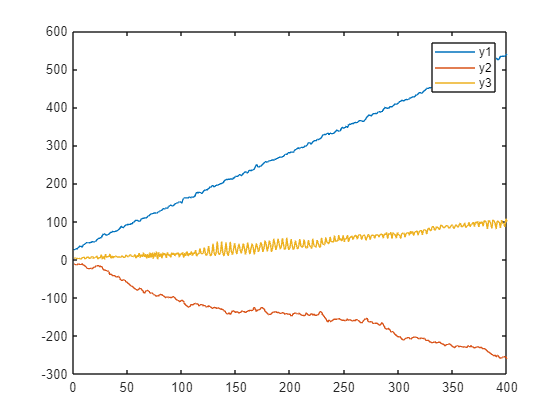

% number of years
T = 100;

% number of seasons: 
S = 4;

% coefficients for MA(1) model.
rho = 0.5;

% generate the noise
u = randn(S*(T+1),3);

% add correlation across dimensions
L = randn(3,3);
u = u*L;

% generate the output 
% first component: MA(1)
x = u(S:end-1,1);
y(:,1) = rho*x(:)+u((S+1):end,1);

% second component: random walk; 
y(:,2) = cumsum(u(5:end,2));

% third component: seasonal random walk;
for s=1:S
    y(s+[0:(T-1)]*S,3)=cumsum(u(s+[0:(T-1)]*S,3));
end

% add linear trend term:
dt = 20+[1:S*T]';
y = y + dt*randn(1,3);

% add a constant
dt(:,2)=1;

% plot result; 
plot(y);
labs = {'y1','y2','y3'};
legend(labs)

## GUI for easy access to analyses

In order to analyze the data, we call the function `analyze_GUI`.

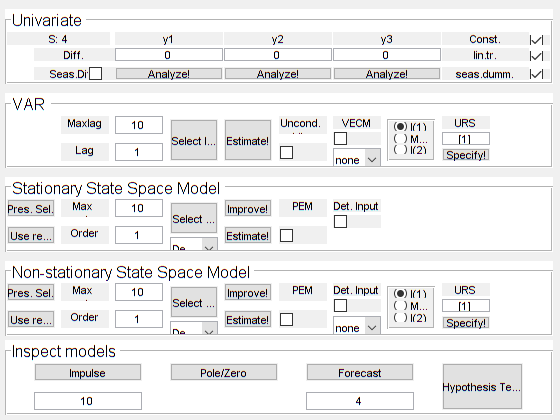

time = 1920+[1:S*T]'/S; % quarterly observations from 1920 to 2019.
analyze_GUI(y,labs,S,zeros(400,0),time);

 The inputs for this function are:

- `y`: Txp real matrix of time series data. Each row is one observation, each column a variable.

- `labs`: cell vector of strings containing the labels for the variables.

- `S`: integer; number of observations per year (in the following called: seasons)

- `dt`: Txk real matrix of deterministic variables: Does not include the constant, a linear trend and seasonal dummies, as these are specified externally. 

- `time`: vector containing the time indices.

The function opens a GUI which provides access to the analysis functions. It contains the following panels:

- **Univariate**: interface for univariate analyses of the various variables. 

- **VAR**: modelling time series using the VAR approaches in levels as well as in error correction representation

- **Stationary State Space Model**: specification and estimation of stationary state space models

- **Non-Stationary State Space Model: **specification and estimation of state space models using the SPECM representation.

- **Inspect models**: analysis of the estimated models. 

### Univariate

In this panel for each of the variables univariate analyses can be accessed. Analyses are performed on differenced time series, where the order of differencing can be provided in the panel. Differencing is first oder (current observation minus last observation) unless the checkbox "Seas. Diff" is checked, in which case yearly differences are calculated. 

The checkboxes allow to select additional deterministic terms in addition to `dt`: a constant, a linear trend and seasonal dummies. Thus in `dt` exogenous variables as well as time dummies or step functions can be included. 

The button "Analyze!" triggers plotting of

- the (differenced) time series

- the residual time series after adjusting for the provided deterministics

- the ACF and PACF for the residual time series.

In addition an augmented Dikey-Fuller test for the existence of a conventional unit root (at frequency zero) and an experimental Portmanteau test for seasonal unit roots (if "Seas Diff." is selected) is printed on the screen. 

The ADF test provides critical values for three levels of significance. The test rejects the null of a unit root at frequency zero, if the test statistic is lower than the critical value. The critical values depend on the specification of the deterministic terms. 

The POortmanteau test provides test statistics for all seasonal unit roots in this case, that is at z=1, z=-1 and z=i, z=-i for quarterly data. The null is rejected, if the test statistic is smaller than the critical values. Deterministic components currently are neglected in the calculation of the critical values. These tests are under development and the implementation is experimental.  

Changing the order of differencing and adding or excluding deterministic variables provides a first input into the suitability of these terms for each variable individually. 

### VAR

The next step in the analysis often is the estimation and specification of a vector autoregressive model (VAR). 

The panel provides three different functionalities:

- `Select lag!` Allows to specify the lag length of the VAR model between zero and an upper bound (`Maxlag`), that can be specified. 

- `Estimate!` Estimates a model with the current specification 

- `Specify!` provides access to estimation and tests on the specification of cointegrating ranks. 

Deterministics here are included from the input `dt` to `analyzeGUI`. Additionally the drop down list below the VECM heading allows to specify deterministic mean and linear trend in the Johansen version of five categories for the I(1) case, see below. 

#### Select Lag

Pressing this button provides two plots and textual output. It calls the function `call_select_VAR`. First the deterministic components are regressed out according to the specification in the univariate panel as well as the provided matrix `dt`. 

Then models in levels are estimated and the corresponding AIC and BIC values are calculated. All estimates are based on OLS on the same part of the data such that the effective sample size is determined by the largest allowed lag length. 

A plot  provides the AIC and BIC values for all tested lag lengths together with an indication of the best choices according to these two criteria. 

A second plot provides the output and the predicted values (left axes) and the residuals (right axes). The two axes are linked such that zooming in on a particular time period zooms in in both subplots. 

The textual output provides basic information as well as the innovation variance estimate according to the best model (according to the AIC). Two estimates are provided, one out of the selection procedure on the reduced data set, one based on the larger data set for the chosen order. 

As output also the selected lag is updated within the GUI. 

#### Specify

Beside the lag length also some integer parameters must be specified for cointegration analysis:

- In the I(1) case this is the cointegrating rank, 

- in the MFI(1) case one cointegrating rank per frequency

- in the I(2) case two ranks correspond to cointegration from I(2) to I(1) and from I(1) to I(0). 

This specification can be done in a number of different ways:

If the model is estimated **in levels**, then the estimate of the VAR polynomial at the potential unit roots provides some hints. The rank of `a(1)` equals the cointegrating rank. The same holds in the MFI(1) case and the rank of `a(z_k)` for all seasonal unit roots `z_k`. For these matrices the SVD is calculated and the singular values multiplied with the sample size plotted as an indication of the cointegrating ranks. The cointegrating rank is estimated crudely as the number of singular values larger than log(T)/T.  

**I(1) case: **For the specification of the cointegrating ranks the vector error correction representation (VECM) is more appropriate. If this checkbox is checked, then the Johansen tests in the VECM are provided in the I(1) case. 

Textual output is produced that provides information for the five different specifications of the deterministics and all possible cointegrating ranks: 

- Unrestricted linear trend and constant.

- Linear trend restricted to the cointegrating relation, constant unrestricted

- No linear trend, constant unrestricted

- No linear trend, constant restricted to the cointegrating relation

- no deterministics.

In our example we added a linear trend to all components. In the I(1) model, however, due to the integration 1+2 produce a linear trend in the output process.  

The textual output provides the values of the deviances for all values of the cointegrating ranks in the rows to the various specified deterministics. 

Beside the textual output also two plots are provided. The plot of the model fit and residuals is accompanied by a diagnostic plot that provides the results of the Johansen trace tests: 

- the test for cointegrating rank equal to zero versus rank equal to `s` is provided at `x` value zero in the plot. The blue bar represents the acceptance region, the star marks the value of the test for the data at hand and the chosen deterministic specification. If the star is above the blue bar, the test is rejected and the procedure continues at x value equal to one.

- at `x` value `i` the test of cointegrating rank `i` versus cointegrating rank `s` is provided. If the star is inside the blue bar region, then the test does not reject and we use this value as the specification, `r=i`. If the star is outside, the test rejects, and we continue at `x` value `i+1`. 

- at `x` value equal to `s-1` the test of cointegrating rank `s-1` versus cointegrating rank equal to `s` is performed. If the star is inside the blue bar region, we use the specification of cointegrating rank equalling `r=s-1`. If it is outside the procedure concludes a cointegrating rank of `r=s`.

Note that the unit root structure equals `s-r` in this case. 

The main function used in for these calculations is `test_Johansen_VECM_I1`.

**MFI(1) case:** In this case we use the procedure of Johansen and Schaumburg (1999), which is similar to the I(1) but specifies the cointegrating rank for each unit root frequency separately. The common cycles corresponding to the other unit roots are concentrated out. 

The output in this case is purely graphical. A figure provides one plot for each potential unit root providing the Johansen trace plot sequence for testing analogously to the I(1) plots above.

The main function used in for these calculations is `test_Johansen_VECM_MFI1`.

**I(2) case:**  In the I(2) case the 2SI2 method of Paruolo (2000) is implemented in the MATLAB function `VECM_2SI2 `for given specification of the two structure parameters (the rank of the matrices $\Pi$ and $\Gamma$) in the equation

$\Delta^2 y_t = \Pi y_{t-1} + \Gamma \Delta y_{t-1} + \sum_{j=1}^{p-2}\Psi_j\Delta^2 y_{t-j} + \mu + e_t$. 

This function is called for all values of the first structure parameter inside the function `test_Johansen_VECM_I2`, which delivers likelihood ratio tests for each combination of the structure parameters. 

The output here is textual providing a matrix output. The rows correspond to the first structure index, the rank r1 of $\Pi$, the columns refer to the rank r2 of $\Gamma.$ Since $r1+ r2 \le s$ the matrix shows NaNs in entries that do not contain useful test results. The test outcomes are scaled by the corresponding 95% critical values, such that values larger than one indicate a rejection of the hypothesis with size 5% and values smaller than one non-rejection. 

The matrix is to be read as follows: Within each row the interpretation follows the iterative Johansen trace test procedure as above: As long as the tests reject, we proceed to the next column. If also the last test is rejected, we continue in the next row. We continue this until for the first time we do not reject. Or until we end at the last test. 

In terms of deterministics in the I(2) case only the inclusion of a constant terms is implemented. No linear trend term or seasonal components are included here. For the specification all five Johansen cases collapse to two here: either no constant is used or an unrestricted constant is included. 

#### Estimate

This estimates the model specified in the VARX panel. The unit root structure is supplied differently for the three cases:

- I(1): unit root structure is given by one integer, the number of common trends

- MFI(1): Here the frequency of the unit roots and the corresponding number of common cycles needs to be specified. Also real unit roots are treated differently than complex unit roots. The unit root structure is a `kx3` real matrix. The first column contains the frequency in fractions of $\pi$(1 corresponds to a unit root being present at frequency $\pi$and unit root z=-1); the second column indicates whether it is a real unit root (0, for z=1, z=-1) or complex (1; all else); the third column is an integer providing the number of common cycles at the unit root frequency ($1 \le c \le s$: if no common cylce is present, this is not a unit root frequency; at most s common cycles are identified). 

- I(2): here the unit root structure is a pair of integers. The first integer r1 denotes the rank of $\Pi$, the integer r2 the rank of $\alpha_\perp' \Gamma \beta_\perp$.  

For the presentation of the estimation results the checkbox 'unconditional' changes the calculation of the likelihood values. It does not change the estimation which is performed using regression in any case, but takes into account that the likelihood typically is calculated conditional on the initial values in the VARX setting. In order to obtain unconditional log likelihood values (mostly for comparison to the corresponding unconditional log likelihood values in the state space framework) also for the VARX case a term is added representing the likelihood of the initial values. This separates the stable and the unstable part of the transfer function. For the stable part we use the corresponding stationary distribution in order to calculate the likelihood contribution. For the unstable part the initial value is estimated and does not contribute to the log likelihood. The textual output provides the estimate of the number of unstable components of the state corresponding to the companion form representation of the VARX system. 

### Stationary State Space Model

This panel provides access to the estimation and specification of state space models. The structure is analogously to the VARX modeling.

In order to estimate a state space model, a number of integer parameters need to be specified:

- n: system order; this denotes the number of state components.

- deterministic input: whether or not there are predefined deterministic input variables. Examples are a linear trend, a constant or seasonal dummy variables. These variables are provided to the analysis GUI as an input variable

- PEM: this checkbox decides whether estimation is performed using the prediction error criterion function, which assumes zero initial values for the state. The prediction error criterion function is formed using the sample variance of the estimated innovations process:


$$\hat \varepsilon_t = \sum_{j=0}^{t-1} K_j^-(y_{t-j} - \Phi d_{t-j})$$


        where $d_t$ denotes the deterministic variables and $K_j ^-$ denotes the impulse response sequence of the inverse transfer function. In this situation the effects of initial values is also estimated to reduce effects from picking wrong initial values (although they do not matter asymptotically, they might make a difference in finite samples). 

If the PEM checkbox is not checked, estimation uses the assumption of a stationary distribution for the components corresponding to the stable part of the transfer function. This corresponds to the unconditional likelihood.  

#### Select Order!

This function is used for the selection of the order of the system. Selection is performed by the criterion indicated in the dropdown menu with the choices being the AIC, the BIC criterion or the deviance. 

The criterion function is highly non-convex and hence estimation often does not lead to a global optimum. This is countered by applying a randomization of the search for the global optimum starting from a typically reasonable starting value. The randomization uses two parameters:

- the number of random trials: given as an integer 

- the size of the random step: randomization uses a simple iid draw of a standard normally distributed pseudo random number, scaled by a standard deviation that can be set. 

In the startup of the procedure five random trials are used. 

When the 'Select Order' button is pressed, for each order from 0 to the one specified under 'Max' a state space system is estimated using the function `cal_select_StSp`. Depending on which checkbox is selected, either the PEM or the pseudo-likelihood criterion is used for estimation. IThe function returns a vector of estimation results called `results_stat` in the workspace. 

#### Improve!

Pressing this button checks, whether a transfer function of the given order `n` has already been estimated and stored in the vector `results_stat` in place n+1. If so, then the function `random_improve` is called for this estimate, which opens a new figure controlling the random improvements algorithms. The result object then defines all parameters and settings for the model class used. 

#### Estimate!

This button provides access to the estimation according to the currently set values of the specification. ***It does not take into account the already defined estimate for the given order, if this is present.  ***

#### Pres selected

This button presents the results for the current specification in the style used for the VARX panel above: Two plots are provided. One presents the value of AIC and BIc over all estimated models. The second one a plot indicating the fit and the residuals for the model corresponding to the order selected in the GUI is provided. 

#### Use Results 

This button allows to add the current estimation result to the list of models. It replaces the current model stored at position `n+1` in the `results_stat` vector. Here `n` denotes the state space dimension of the current estimation result. 

### Non-Stationary State Space Models

This panel allows for the estimation of non-stable models including unit roots. The basic structure is analogous to the stationary model panels, but additional capabilities relate to the specification of the model. Again the PEM criterion function can be selected, deterministic input according to the specification in the univariate panel can be included. 

For the specification the five Johansen variants can be selected. 

#### Select Order!

This function is used for the selection of the order of the system. 

When the 'Select Order' button is pressed, for each order from 0 to the one specified under 'Max' a state space system is estimated using the function `cal_select_SPECM`. Depending on which checkbox is selected, either the PEM or the pseudo-likelihood criterion is used for estimation. Depending on the checkbox I(1), MFI(1) or I(2) models are estimated, where the state space unit root structure is provided in the form of the unit root structure in the field `URS`. 

The structure of the field is different for the three different cases. 

I(1): `URS` is an integer specifying the number of common trends. 

MFI(1): URS is a matrix containing one row for each 

Initialization is provided using the stationary systems, if they are available. The Ribarits-Hanzon approach is used to obtain starting values based on the stationary estimate. 

The function returns a vector of estimation results called `results` in the workspace. 

#### Improve!

Pressing this button checks, whether a transfer function of the given order `n` has already been estimated and stored in the vector `results_stat` in place n+1. If so, then the function `random_improve` is called for this estimate, which opens a new figure controlling the random improvements algorithms. The result object then defines all parameters and settings for the model class used. 

#### Estimate!

This button provides access to the estimation according to the currently set values of the specification. ***It does not take into account the already defined estimate for the given order, if this is present. However, if a stationary system of the given order is estimated, then this is used for obtaining a starting value.  ***

#### Pres selected

This button presents the results for the current specification in the style used for the VARX panel above: Two plots are provided. One presents the value of AIC and BIc over all estimated models. The second one a plot indicating the fit and the residuals for the model corresponding to the order selected in the GUI is provided. 

#### Use Results 

This button allows to add the current estimation result to the list of models. It replaces the current model stored at position `n+1` in the `results` vector. Here `n` denotes the state space dimension of the current estimation result. 

#### Specify!

This button allows to call specification procedures. Depending on the model class (I(1), MFI(1) or I(2)) differing specification tests are calculated. All use the SPECM formulation and provide output analogous to the one in the VARX panel. 

### Inspect Models

Beside the plot of the fit for the model at hand a number of additional characteristics are worth investigating. These can be accessed in the last panel, where the models are stored from the state space model panel:

- **Impulse**: This button provides a plot of the impulse response sequence for all selected models. The edit field allows to control the time horizon. 

- **Pole/zero**: This button provides a pole/zero plot

- **Forecast**: Using this button the forecasting performance of the models can be explored. The edit field below lets control the forecasting horizon.

- **Hypothesis**: This button provides access to hypothesis tests in the I(1) and MFI(1) case. Tests involve hypotheses on $\beta$ and/or $\alpha$. 

The input to the functions here is assumed to be stored in a vector called `ths` in the workspace. This allows for a flexible combination of different model structures. The functions work for both vectors of estimated systems in the form of `theta` structures or estimation results (in the form of `est_results` objects). As a vector needs to be supplied it is not possible to mix the two (that is either all est_results or all theta structures need to be supplied). 

#### Impulse

This button provides access to a plot of the impulse response sequence. It reads in the vector `ths`, which contains a number of `theta` structures of estimated systems. The editable field below the button allows to specify the temporal horizon, that is how many period ahead the impulse response is to be calculated. 

#### Pole/zero 

This button provides a pole/zero plot for the transfer functions provided in the vector `ths`. For every rational transfer function a pole is defined as an eigenvalue of the matrix A, a zero is defined as an eigenvalue of the matrix A-KC. Note that these correspond to the inverses of poles and zeros in the ARMA context. 

#### Forecast

This button provides access to forecasting comparisons of the various estimated models. These are read from the vector `result` (can also be just one element). The editable number below allows to specify a forecasting horizon in the number of periods. Setting it to 1 results in one period ahead predictions, setting it to 4 for quarterly data corresponds to one year ahead prediction. 

The forecasts are started assuming a stationary distribution for the state. In case of a pole close to the unit circle this may lead to a strong inflation and correspondingly large residuals at the start. 

#### Hypothesis

Tests on hypotheses on the cointegrating space and the adjustment matrices corresponding to the Johansen machinery are contained in the function `RH_specm_H0` and `RH_specm_Ha` for the I(1) case and `RH_SPECM_MFI1_H` for the MFI(1) case. 

A number of hypotheses are testable including fixed $\beta$, $\beta$ containing a particular column and $\beta = H\varphi$ as well as $\alpha$ fixed or $\alpha$ containing a fixed column. Also mixing the two hypotheses is possible, see the help for the two procedures. 

In the MFI(1) case only restrictions on realness of $\beta$ and/or $\alpha$ are implemented as of now. 